% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time.

% set input and output paths:
input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
output_path = '\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

% 1- ICA on preprocessed epoched data
% What preprocessing has been done:
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Plotting...


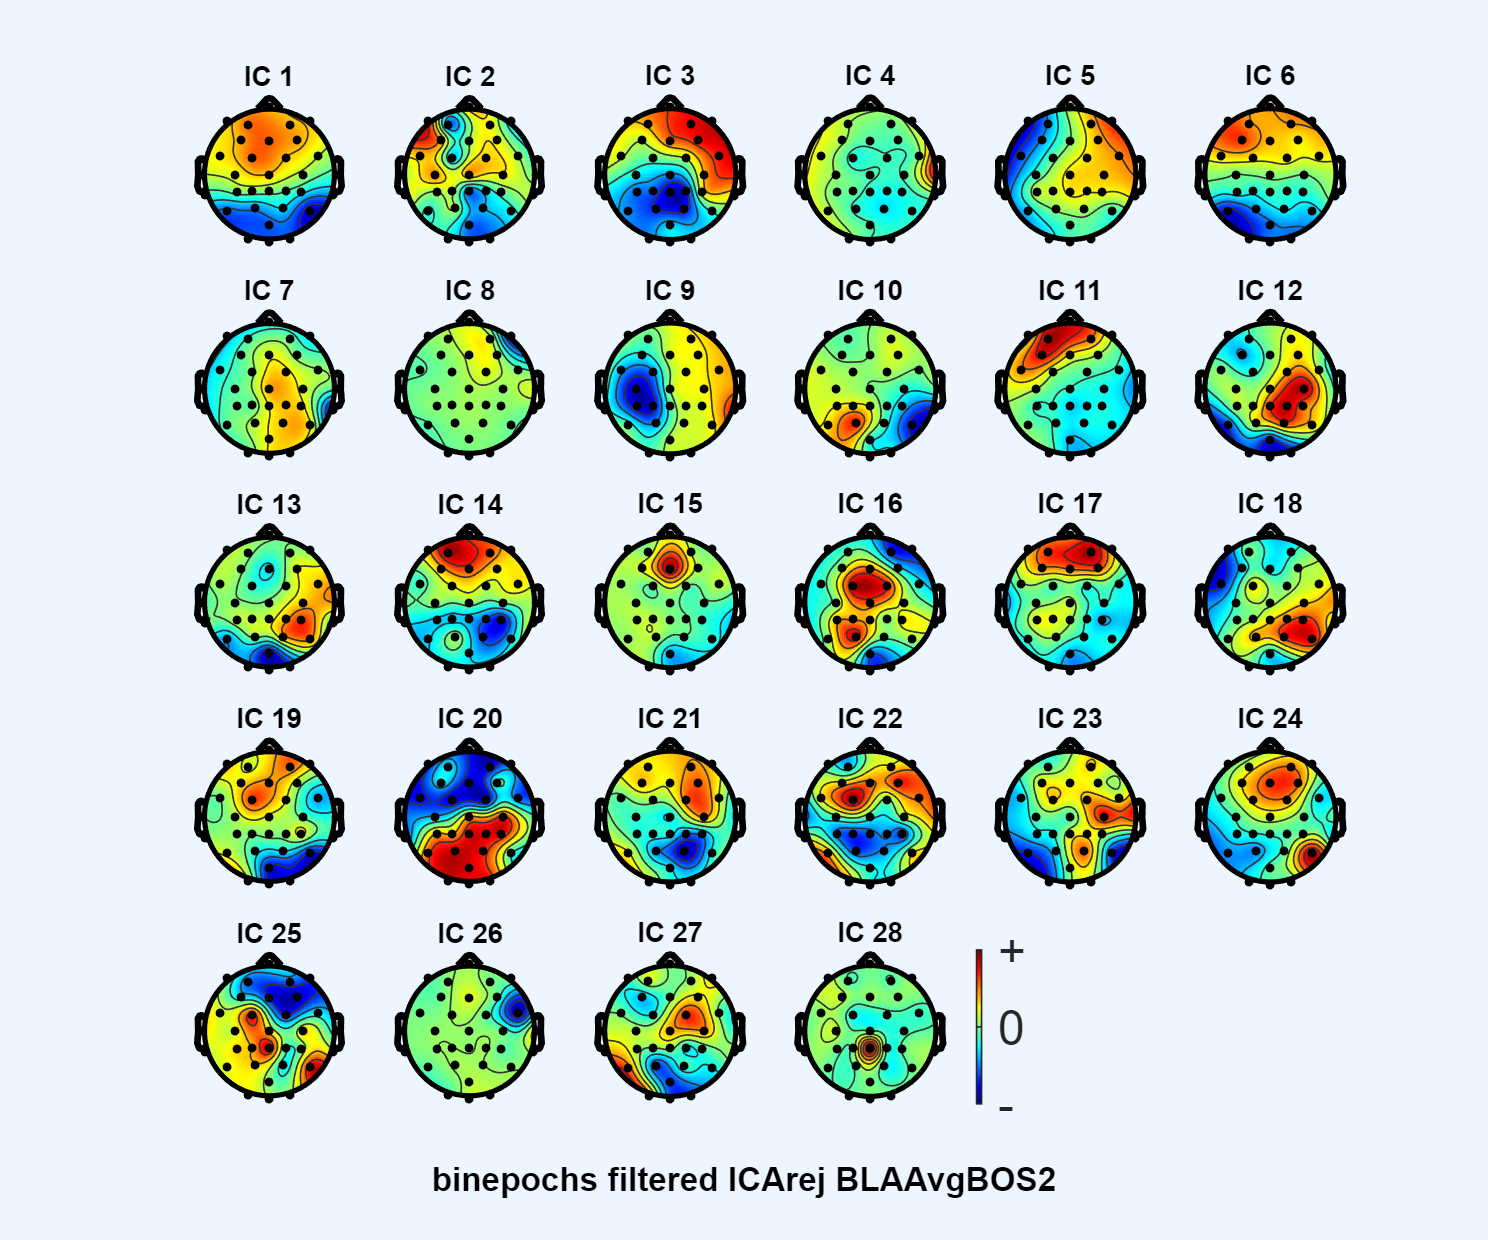

pop_topoplot(EEG, 0, [1:28] ,'binepochs filtered ICArej BLAAvgBOS2',[5 6] ,0,'electrodes','on');

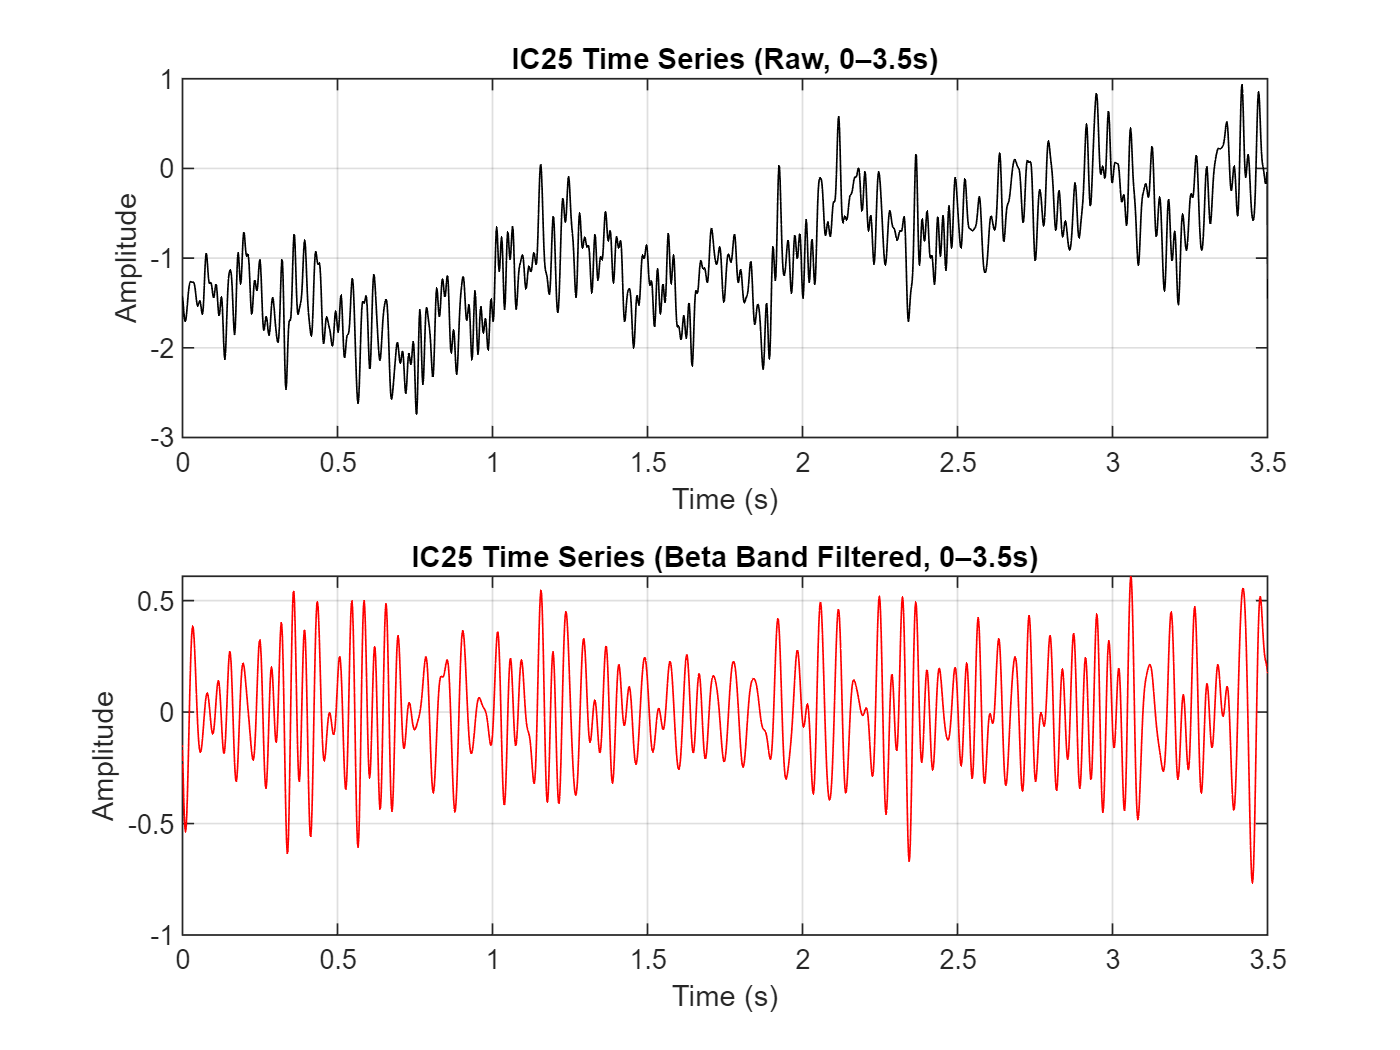


% - First we will do the PCA for just one IC over the somatosensory cortex
% and later loop over all ICs.
% IC25 for BLAAvgBOS2 falls over left central

% - Visualize ICs and chose the IC over left somatosensory cortex
fs = EEG.srate; % Sampling frequency in Hz
ic_data = EEG.icaact(25, :); % IC time series
time_vector = (0:length(ic_data)-1) / fs; % Time in seconds

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
beta_band = [13 30];
% Bandpass filtering:

beta_signal = bandpass(ic_data, beta_band, fs);

% Define time range for plotting (0 to 3.5 seconds)
time_limit = 3.5; % seconds
idx_range = time_vector <= time_limit; % Logical index for the range

% Plot IC time series before and after filtering (limited to 0-3.5s)
figure;
subplot(2,1,1);
plot(time_vector(idx_range), ic_data(idx_range), 'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('IC25 Time Series (Raw, 0–3.5s)');
xlim([0 time_limit]);
grid on;

subplot(2,1,2);
plot(time_vector(idx_range), beta_signal(idx_range), 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('IC25 Time Series (Beta Band Filtered, 0–3.5s)');
xlim([0 time_limit]);
grid on;

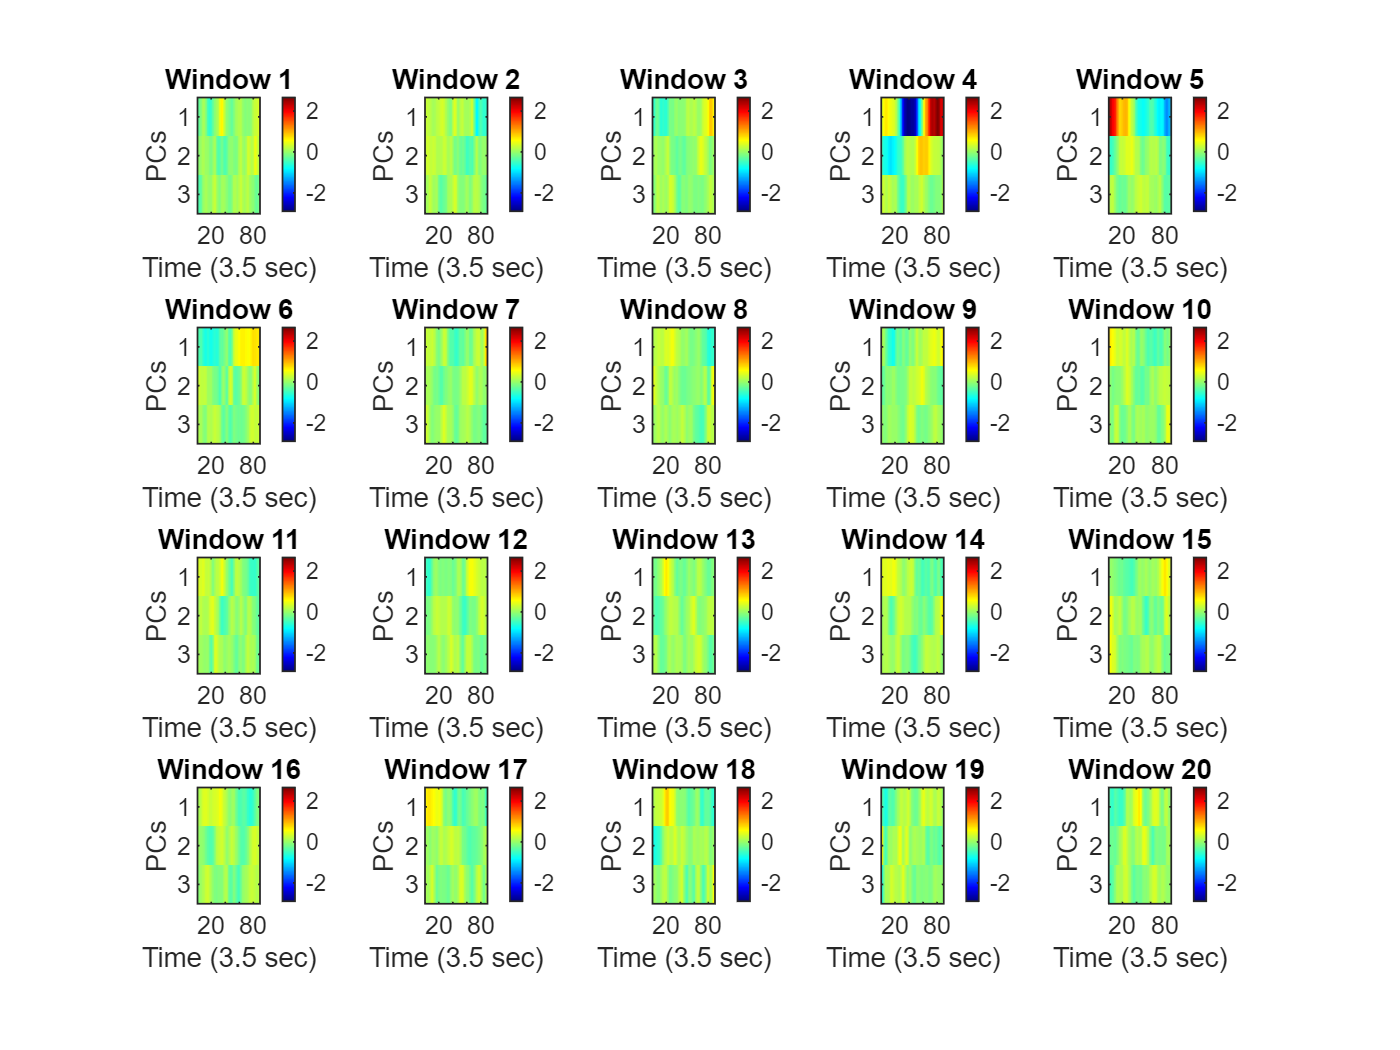


% 2- PCA 
% - 2.1 PCA across space: across IC space
% - bin average of 3 trials together (3 epochs): 60 trials/3 = 20 latent
% space images per condition

% For the BLA, BLT and P1, we choose the odd epochs to correspond with auditory onset. 
% Step 1: Extract the odd epochs (epochs 1, 3, 5, ..., 119)
odd_epochs = 1:2:EEG.trials; % Select odd epoch indices

% Step 2: Extract the ICA activations for the selected epochs
% EEG.icaact has dimensions (nICs x nSamples x nEpochs)
ic_data_odd = EEG.icaact(:, :, odd_epochs); % Select odd epochs

% Step 3: Compute the average IC activations across selected epochs
avg_ic_data = mean(ic_data_odd, 3); % Average over epochs

% Step 4: Define time windows
num_windows = 20; % Number of time segments
window_size = floor(size(avg_ic_data, 2) / num_windows); % Divide into equal parts:
% each epoch 3.5 sec x512 sample/sec = 1792
% 1792/20 = 89.6, floor(89.6)= 89 samples for window size

% Step 5: Compute PCA for all time windows and find global min/max for color scale
all_scores = []; % Store all PC scores to determine global min/max

for w = 1:num_windows
    % Define time window range
    start_idx = (w-1) * window_size + 1;
    end_idx = min(w * window_size, size(avg_ic_data, 2));
    
    % Extract the time-segmented data, 89 time points
    window_data = avg_ic_data(:, start_idx:end_idx);
    
    % Perform PCA on the selected time window
    [coeff, score, ~] = pca(window_data', 'NumComponents', 3); % 'score' contains PCs
    
    % Store scores to determine global min/max
    all_scores = [all_scores; score]; 
end

% Get global min and max for consistent color scale
global_min = min(all_scores(:));
global_max = max(all_scores(:));

% Step 6: Plot heatmaps with the same scale
figure;
for w = 1:num_windows
    % Define time window range
    start_idx = (w-1) * window_size + 1;
    end_idx = min(w * window_size, size(avg_ic_data, 2));
    
    % Extract the time-segmented data
    window_data = avg_ic_data(:, start_idx:end_idx);
    
    % Perform PCA on the selected time window
    [coeff, score, ~] = pca(window_data', 'NumComponents', 3); % 'score' contains PCs
    
    % Plot heatmap for the top 3 PCs in a subplot
    subplot(4,5,w); % 4 rows x 5 columns = 20 subplots
    imagesc(score'); % Transpose to align dimensions correctly
    colormap jet;
    caxis([global_min global_max]); % Use the same color scale for all plots
    colorbar;
    xlabel('Time (3.5 sec)');
    ylabel('PCs');
    title(['Window ' num2str(w)]);
end


% - 2.2 PCA across time: Higher temporal resolution latent dynamics with a sliding window of 50
% ms, and 25 ms overlap. 
